clear
close all
clc

# IIR design-metoder

Formålet er at anvende MATLAB til design og analyse af digitale IIR-filtre. IIR-filterets overføringsfunktion H(z) designes ud fra et analogt prototypefilter H(s), der transformeres til H(z).

Dernæst "kontrol-designes" IIR-filteret direkte i det digitale domæne vha. GUI'en "FDATool".

## Eksempel 1: Beregning af digitalt IIR-båndpasfilter

Der ønskes et Butterworth-båndpasfilter konstrueret med følgende specifikationer:

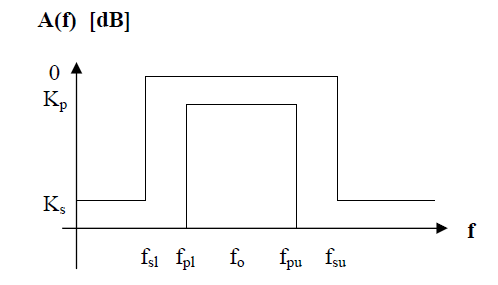

fs = 10000;
fsl = 1000;
fpl = 1800;
fo = 2000;
fpu = 2200;
fsu = 4000;
Kp = 3; % -3 dB
Ks = 40; % -40 dB

Der tages udgangspunkt i et analogt filter, hvis filterorden findes med "buttord".

[N Wn] = buttord([2*pi*fpl 2*pi*fpu],[2*pi*fsl 2*pi*fsu],Kp,Ks,'s')

N = 3

Wn = 	1.0e+04 *

    1.0659    1.4666


Beregn det analoge filter med "butter".

[bs as] = butter(N,Wn,'s');
Hs = tf(bs,as)


Hs =
 
                                     6.433e10 s^3
  ----------------------------------------------------------------------------------
  s^6 + 8014 s^5 + 5.011e08 s^4 + 2.57e12 s^3 + 7.834e16 s^2 + 1.959e20 s + 3.821e24
 
Continuous-time transfer function.



Båndpasfilteret er et sjetteordensfilter.

Kontrollér om kravene er overholdt med "bode".

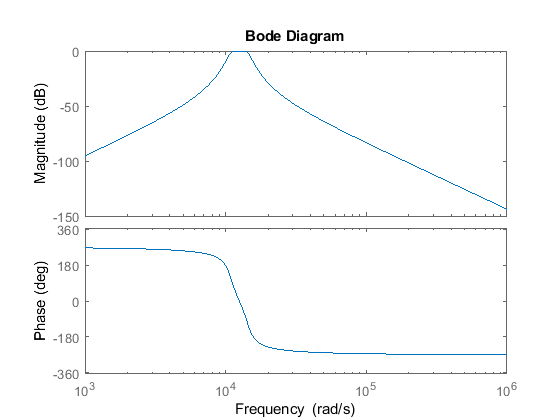

bode(Hs)

Det analoge filter ønskes transformeret til et digitalt IIR-filter. I første omgang anvendes Impuls Invarians-metoden.

[bz az] = impinvar(bs,as,fs);
Hz = tf(bz,az,1/fs)


Hz =
 
  -8.185e-16 z^6 + 0.01533 z^5 - 0.0345 z^4 + 0.009827 z^3 + 0.02162 z^2 - 0.01242 z
  ----------------------------------------------------------------------------------
        z^6 - 1.644 z^5 + 3.116 z^4 - 2.629 z^3 + 2.39 z^2 - 0.9583 z + 0.4487
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



Kontrollér om kravene er overholdt med "freqz".

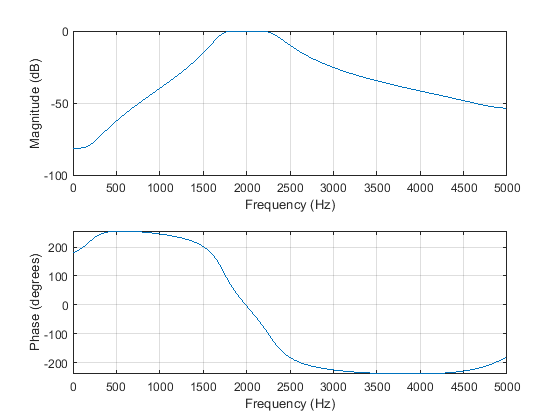

freqz(bz,az,1024,fs)

Amplitudedæmpningen flader ud ved frekvenser tæt på fs/2 grundet aliasing. Dette ses også, når der kigges på poler/nulpunkter, idet der ligger nulpunkter omkring den +1 og -1 på den reelle akse.

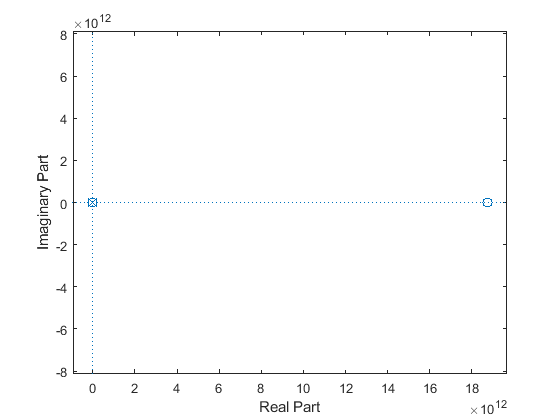

zplane(bz,az)

Det analoge filter ønskes nu transformeret til IIR-filter ved hjælp af Bilineær Transformation-metoden.

[bz az] = bilinear(bs,as,fs);
Hz = tf(bz,az,1/fs)


Hz =
 
  0.002243 z^6 - 4.441e-16 z^5 - 0.006729 z^4 + 0.006729 z^2 + 6.661e-16 z - 0.002243
  -----------------------------------------------------------------------------------
        z^6 - 2.378 z^5 + 4.323 z^4 - 4.394 z^3 + 3.572 z^2 - 1.621 z + 0.5631
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



Kontrollér om kravene er overholdt med "freqz".

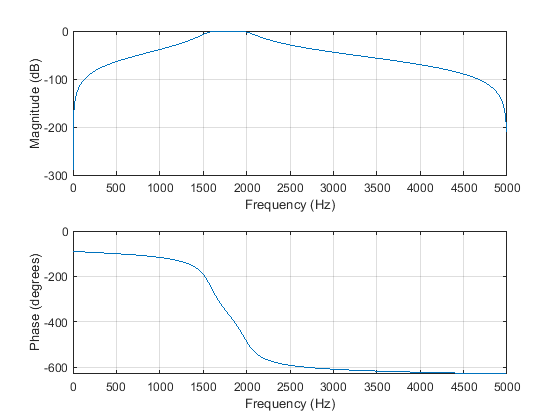

freqz(bz,az,1024,fs)

Der optræder warping af frekvenserne. Dette forsøges opvejet med pre-warping.

[bz az] = bilinear(bs, as, fs, fo);
Hz = tf(bz,az,1/fs)


Hz =
 
                                                                                                  
  0.002601 z^6 + 1.554e-15 z^5 - 0.007804 z^4 - 1.776e-15 z^3 + 0.007804 z^2 - 2.887e-15 z        
                                                                                                  
                                                                                        - 0.002601
                                                                                                  
  ------------------------------------------------------------------------------------------------
                                                                                     
               z^6 - 1.693 z^5 + 3.358 z^4 - 2.918 z^3 + 2.747 z^2 - 1.129 z + 0.5453
                                                                                     
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



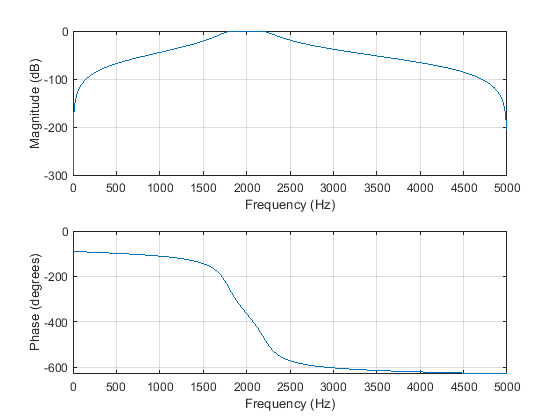

freqz(bz,az,1024,fs)

Til sidst beregnes det digitale filter direkte fra kravene uden først at beregne det analoge filter.

[N Wn] = buttord([fpl/(fs/2) fpu/(fs/2),],[fsl/(fs/2) fsu/(fs/2)], Kp, Ks);
[bz az] = butter(N,Wn);
Hz = tf(bz,az,1/fs)


Hz =
 
           0.00422 z^6 - 0.01266 z^4 + 0.01266 z^2 - 0.00422
  --------------------------------------------------------------------
  z^6 - 1.645 z^5 + 3.19 z^4 - 2.711 z^3 + 2.511 z^2 - 1.013 z + 0.484
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



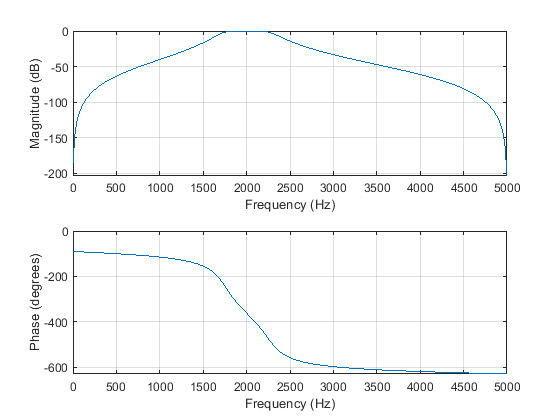

freqz(bz,az,1024,fs)

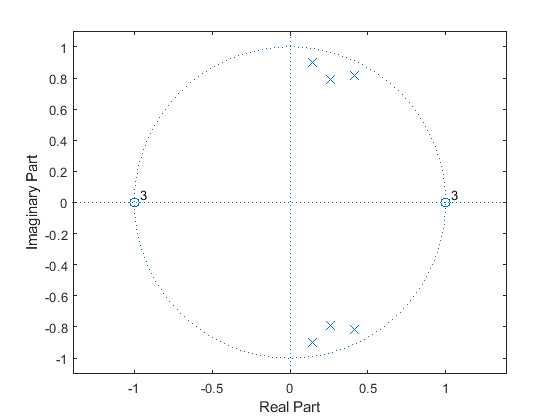


zplane(bz,az)

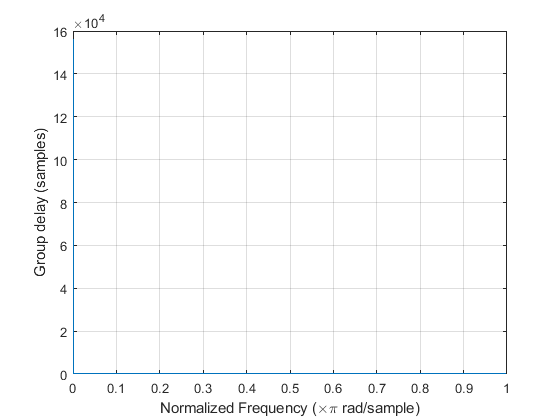

grpdelay(bz,az)

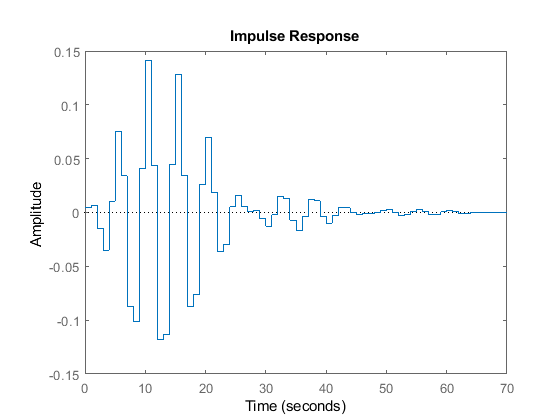

dimpulse(bz,az)

## FDATool

GUI'en FDATool (Filter Design and Analysis Tool) anvendes

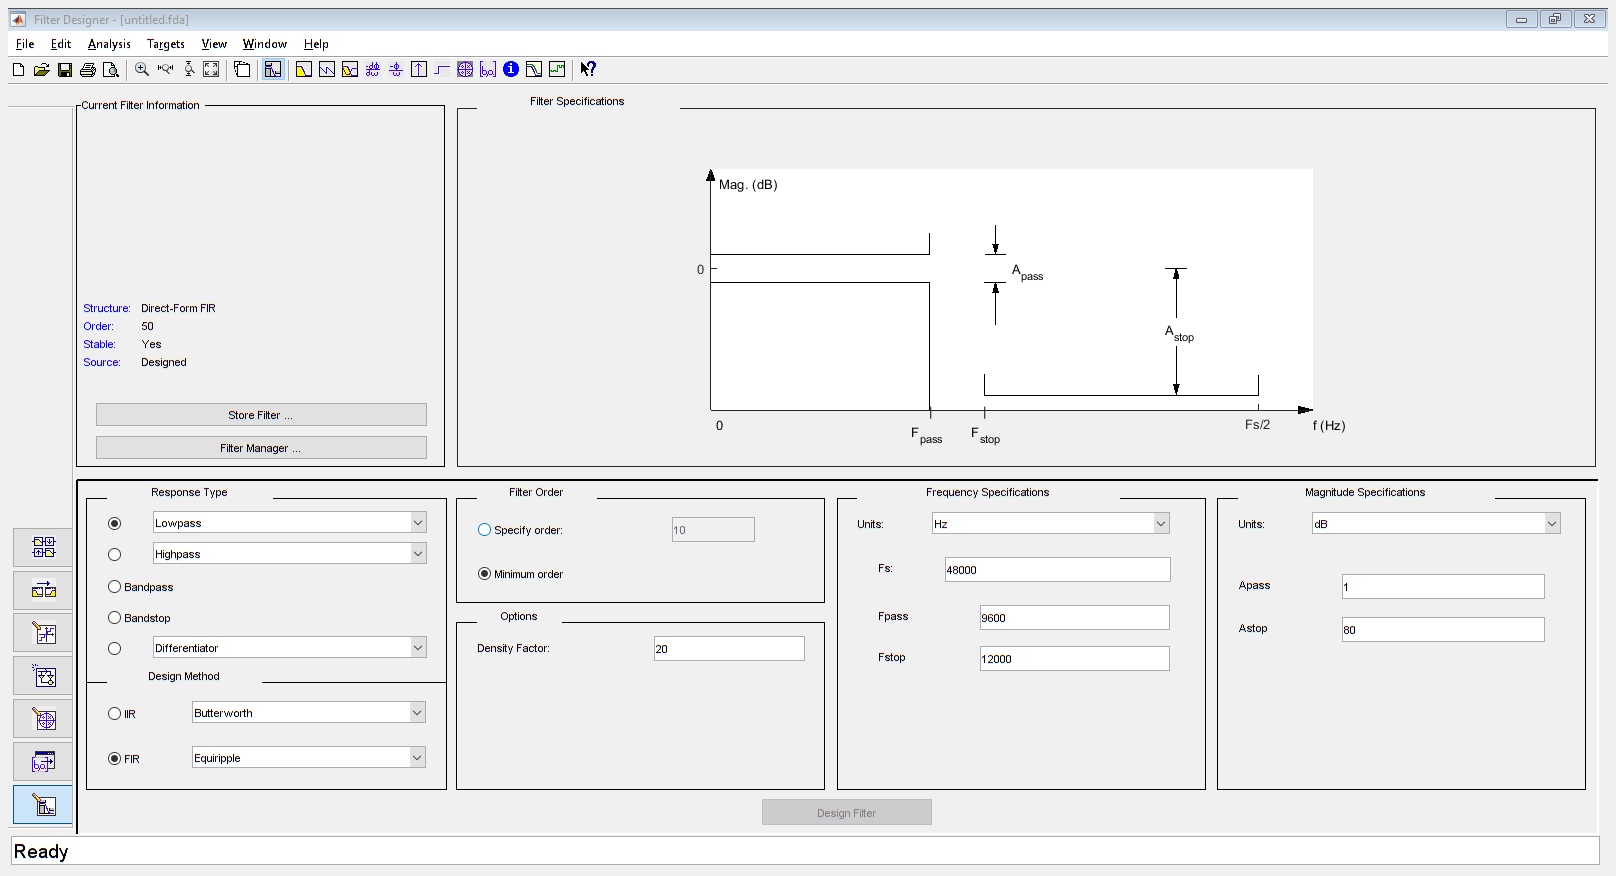

filterDesigner

## Eksempel 2

Opstil selv kravene til et Butterworth IIR-lavpasfilter med afskæringsfrekvens på 1 kHz og samplingfrekvens på 10 kHz. Beregn filteret.

fs = 10000;
fpas = 1000;
fstop = 3500;
Ap = 3;
As = 72;

% Find analogt filter
[N, Wn] = buttord(2*pi*fpas,2*pi*fstop,Ap,As,'s')

N = 7

Wn = 6.7292e+03

[bs as] = butter(N,Wn,'s');
Hs = tf(bs,as)


Hs =
 
                                                      
                                              6.248e26
                                                      
  ------------------------------------------------------------------------------------------------
                                                                                                  
  s^7 + 3.024e04 s^6 + 4.572e08 s^5 + 4.446e12 s^4 + 2.992e16 s^3 + 1.393e20 s^2 + 4.173e23 s     
                                                                                                  
                                                                                        + 6.248e26
                                                                                                  
 
Continuous-time transfer function.



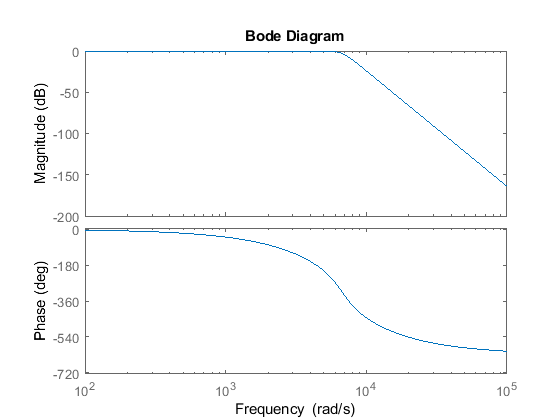

bode(Hs)


% Konverter fra analog til digital med ImpInvar
[bz az] = impinvar(bs,as,fs);
Hz = tf(bz,az,1/fs)


Hz =
 
                                                                                                  
  2.092e-14 z^7 + 5.566e-05 z^6 + 0.002 z^5 + 0.006763 z^4 + 0.0044 z^3 + 0.0005493 z^2           
                                                                                                  
                                                                                     + 6.424e-06 z
                                                                                                  
  ------------------------------------------------------------------------------------------------
                                                                                           
        z^7 - 4.056 z^6 + 7.444 z^5 - 7.897 z^4 + 5.189 z^3 - 2.101 z^2 + 0.4833 z - 0.0486
                                                                                           
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



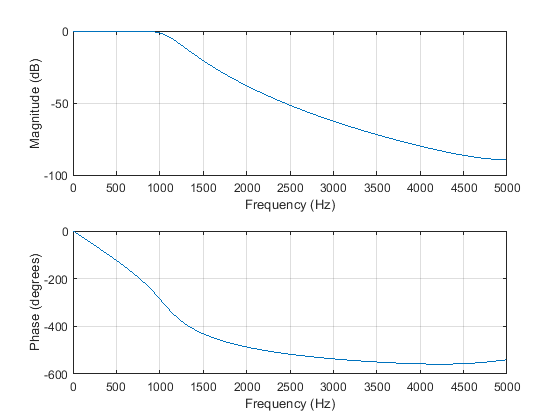

freqz(bz,az,1024,fs)


% Konverter fra analog til digital med Bilineær Transformation
[bz az] = bilinear(bs,as,fs);
Hz = tf(bz,az,1/fs)


Hz =
 
                                                                                                  
  0.0001097 z^7 + 0.0007681 z^6 + 0.002304 z^5 + 0.00384 z^4 + 0.00384 z^3 + 0.002304 z^2         
                                                                                                  
                                                                         + 0.0007681 z + 0.0001097
                                                                                                  
  ------------------------------------------------------------------------------------------------
                                                                                            
        z^7 - 4.089 z^6 + 7.561 z^5 - 8.072 z^4 + 5.332 z^3 - 2.168 z^2 + 0.5008 z - 0.05053
                                                                                            
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



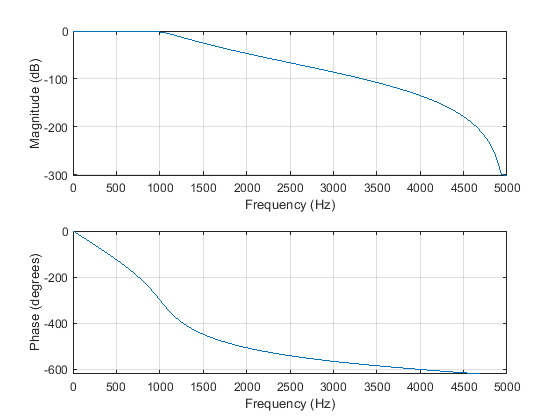

freqz(bz,az,1024,fs)


% Beregn digitalt filter direkte uden analogt filter
[N Wn] = buttord(fpas/(fs/2),fstop/(fs/2),Ap,As)

N = 5

Wn = 0.2278

[bz az] = butter(N,Wn);
Hz = tf(bz,az,1/fs)


Hz =
 
  0.002225 z^5 + 0.01113 z^4 + 0.02225 z^3 + 0.02225 z^2 + 0.01113 z + 0.002225
  -----------------------------------------------------------------------------
          z^5 - 2.696 z^4 + 3.227 z^3 - 2.043 z^2 + 0.6761 z - 0.09256
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



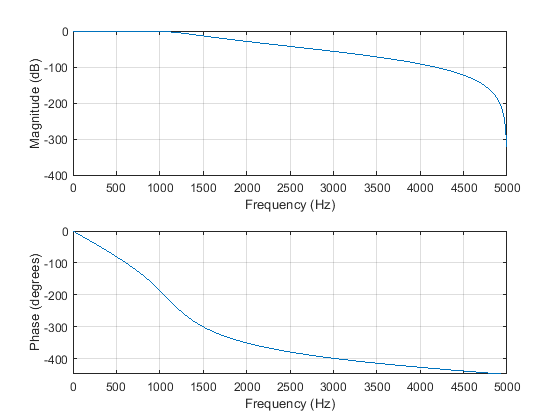

freqz(bz,az,1024,fs)